# Dynamics and motion control

## Modeling and Control of Robotic Manipulators

#### 1. Open Simscape Model

 Open the Simscape model of the two link arm and specify the model workspace variables for the geometric and dynamic parameters.

% open Simscape model
if verLessThan('matlab','9.3')  % Release 2017a
    mdlFile='twolinkarmR2017a';
elseif verLessThan('matlab','9.5')  % Release 2018b
    mdlFile='twolinkarmR2017b';
else
    mdlFile='twolinkarm';
end
twoLinkArmMdl=open(mdlFile);

% Set workspace variables
rhoe = 0; % density pay load (sphere) kg/m^3
re = 0.1; % radius sphere payload
rho = 1000; % density link bodies (cylinder) kg/m^3
mu = 0.0; % joint friction coefficient Nm / (deg/s)   % task 1-3
a1 = 1.0; % link length arm 1
a2 = 1.0; % link length arm 2
r1 = 0.05; % radius arm 1
r2 = 0.05; % radius arm 2

% Assign workspace variables to simscape model
hws = get_param(bdroot, 'modelworkspace');
hws.assignin('rhoe',rhoe);
hws.assignin('rho',rho);
hws.assignin('a1',a1);
hws.assignin('a2',a2);
hws.assignin('r1',r1);
hws.assignin('r2',r2);
hws.assignin('re',re);
hws.assignin('mu',mu);


#### 2. Simulate ego-motion

Simulate the ego-motion of the two link planar arm under gravity without friction and with zero torque input $$\mathbf{\tau}=[0 \ 0]$$ in Simscape for an initial joint state $$\mathbf{q}_0=[-\pi/4 \ \pi/4] , \  \dot{\mathbf{q}}_0=[0 \ 0] $$ over a period $$t \in [0, 10]$$.

% define simulation input torque profile for time series
tfinal = 10;
dt = 0.005;
tspan = [0 tfinal];

tauSimIn = timeseries([0 0],[tfinal],'Name','tau'); % free motion zero torque

qzero = [-pi/4 pi/4];
qdotzero = [0 0];

xInitial = [qzero(1) qdotzero(1) qzero(2) qdotzero(2) 0 0 0 0];
simOut = sim(mdlFile,'StopTime',num2str(tfinal),'SaveState','on','StateSaveName','xout','LoadInitialState','on','InitialState','xInitial');


#### 3. Plot the joint states

The SimulationObject *simOut* contains the simulation states *simOut.xout* as time series objects. *simOut.xout{1}.Values* refers to joint states $$q_1(t)$$, *simOut.xout{3}.Values* refers to joint states $$q_2(t)$$. Plot the time series of joint states $$q_1(t), q_2(t)$$ as shown in figure 5 with the helper function `plotJointMotion`. You can provide vectors of zeros to ignore the joint velocity.

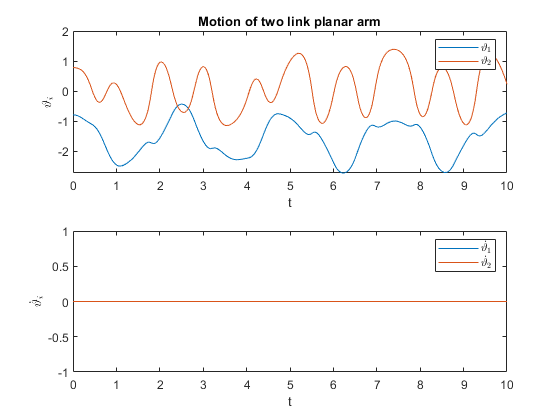

% Extract time series objects
tsq1 = simOut.xout{1}.Values; % twolinkarm.Revolute_Joint1.Rz.q
tsq2 = simOut.xout{3}.Values; % 'twolinkarm.Revolute_Joint2.Rz.q

% Plot (joint velocities set to zero)
figure
plotJointMotion([tsq1.Time],[tsq1.Data tsq2.Data zeros(size(tsq1.Data)) zeros(size(tsq2.Data))]);

#### 4. Simulate ego-motion with a friction parameter

Set the friction parameter $$\mu=0.3$$ and simulate the ego-motion of the two link arm for the same initial state $$\mathbf{q}_0=[-\pi/4 \ \pi/4] , \  \dot{\mathbf{q}}_0=[0 \ 0] $$. Plot the time series of joint states $$q_1(t), q_2(t)$$.

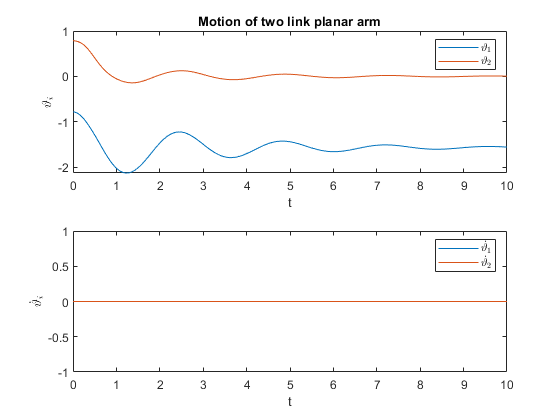

mu = 0.3; % joint friction coefficient Nm / (deg/s)
hws.assignin('mu', mu);

% re-run sections of task 2 and 3 for simulating and plotting, respectively
simOut = sim(mdlFile,'StopTime',num2str(tfinal),'SaveState','on','StateSaveName','xout','LoadInitialState','on','InitialState','xInitial');
tsq1 = simOut.xout{1}.Values; % twolinkarm.Revolute_Joint1.Rz.q
tsq2 = simOut.xout{3}.Values; % 'twolinkarm.Revolute_Joint2.Rz.q

% Plot (joint velocities set to zero)
figure
plotJointMotion([tsq1.Time],[tsq1.Data tsq2.Data zeros(size(tsq1.Data)) zeros(size(tsq2.Data))]);

#### 5. Simulate motion for a torque profile

Simulate the motion for a torque profile that is zero for $$t \in [0 \ 2.5]s$$ increases linearly to $$\mathbf{\tau}=[120 \ 40]$$ over the interval $$t \in [2.5 \ 5]s$$ and then remains constant for $$t \in [5 \ 10]s$$. Start the motion from the initial lower equilibrium state with the arm hanging down $$\mathbf{q}_0=[-\pi/2 \ 0] , \  \dot{\mathbf{q}}_0=[0 \ 0] $$. Plot the time series of joint states $$q_1(t), q_2(t)$$.

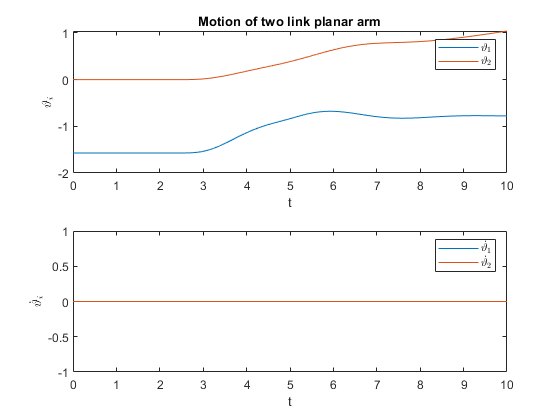

qzero = [-pi/2 0];
qdotzero =[0 0];
xInitial = [qzero(1) qdotzero(1) qzero(2) qdotzero(2) 0 0 0 0];
taufinal = [120 40];
tauSimIn = timeseries([0 0; 0 0; taufinal; taufinal],[0 tfinal/4 tfinal/2 tfinal],'Name','tau'); % Note: auto interpolation
simOut = sim(mdlFile,'StopTime',num2str(tfinal),'SaveState','on','StateSaveName','xout','LoadInitialState','on','InitialState','xInitial');

% re-run section of task 3 for plotting

% Extract time series objects
tsq1 = simOut.xout{1}.Values; % twolinkarm.Revolute_Joint1.Rz.q
tsq2 = simOut.xout{3}.Values; % 'twolinkarm.Revolute_Joint2.Rz.q

% Plot (joint velocities set to zero)
figure
plotJointMotion([tsq1.Time],[tsq1.Data tsq2.Data zeros(size(tsq1.Data)) zeros(size(tsq2.Data))]);

#### Example: Previous task 2 and 4 using robotics system toolbox

Simulation of the Motion of two link planar arm under gravity with no friction and with viscous friction  using robotics system toolbox

%% Robot Dynamics in Robotics System Toolbox

if verLessThan('matlab','9.5')  % Release 2018b
    load 'twolinkarm.mat'  % Load RigidBodyTree from MAT-File
else
    robot = importrobot(gcs);  % import Rigid Body Tree from Simscape
    
    % add body for end effector
    body3 = robotics.RigidBody('Body3');
    jnt3 = robotics.Joint('Joint3','fixed');
    body3.Mass = 1e-6;
    body3.Inertia = [1e-6 1e-6 1e-6 0 0 0];
    jnt3.setFixedTransform(trvec2tform([0 a2 0]));
    body3.Joint = jnt3;
    robot.addBody(body3,'Body2');
    
    % add visuals for link bodies to RigidBodyTree object
    addVisual(robot.Bodies{1,2},'Mesh','cylinder.stl',eul2tform([0 0 -pi/2]));
    addVisual(robot.Bodies{1,1},'Mesh','cylinder.stl',eul2tform([0 0 -pi/2]));
    addVisual(robot.Bodies{1,3},'Mesh','sphere.stl');
end

robot.DataFormat='column';

%% Previous task 2 using robotics system toolbox

% simulate
[t,q] = ode45(@(t,q) [q(3) q(4) robot.forwardDynamics(q(1:2),q(3:4))']'  , [0 tfinal], [-pi/4 pi/4 0 0]);

figure
titletext='Motion of two link planar arm under gravity with no friction.';
plotJointMotion(t,q,titletext);

%% Previous task 4 using robotics system toolbox

mu=0.3; % joint friction coefficient Nm / (deg/s)
Fv=[mu*180/pi; mu*180/pi];  % viscous friction Nm / (rad/s)

% simulate
[t,q] = ode45(@(t,q) [q(3) q(4) robot.forwardDynamics(q(1:2), q(3:4), -Fv.*q(3:4))']'  , [0 tfinal], [-pi/4 pi/4 0 0]);

figure
titletext='Motion of two link planar arm under gravity with viscous friction.';
plotJointMotion(t,q,titletext);


#### 6. Simulate the joint motion

Simulate the joint motion of the two link arm with `ode45` according to the code. The simulation output $$[t, q]$$ contains the vector of discrete simulation time steps $$t_i$$ in conjunction with the corresponding joint states $$[\mathbf{q}(t_i), \dot{\mathbf{q}}(t_i)]$$.

% constant torque
tsteps=linspace(0,tfinal,tfinal/dt); % time steps discretization of torque profile
tau=zeros(size(tsteps,2),2); % zero torque

% we delay the torque values a little bit for better visualization
tau(ceil(size(tau)/10):size(tau),1)=50.0; % external torque joint 1
tau(ceil(size(tau)/10):size(tau),2)=20.0; % external torque joint 2

% initial state ode q_1 q_2 dot q_1 dot q_2
qinitialstate=[-pi/2 0 0 0]; % lower equilibrium

% simulate
% [t,q] = ode45(@(t,q) [... ... robot.forwardDynamics(q(1:2), q(3:4), interp1(tsteps,tau,t)')']'  , [0 tfinal], qinitialstate);


#### 7. Plot the joint motion

Plot the joint motion $$\mathbf{q}(t) =[\vartheta_1(t) , \vartheta_2(t), \dot \vartheta_1(t), \dot \vartheta_2(t)]$$  obtained from numerical integration w.r.t.~time as illustrated in Figure 7 with the helper function `function [] = plotJointMotion( t, q )	`

figure
titletext='Motion of two link planar arm under gravity and constant external torque.';
% plotJointMotion(...,...,...);

#### 8. Simulate with viscous friction term

Include a viscous friction term $$\tau_{{v}_i} = -F_{v_i} \dot \vartheta_i$$ in the simulation of the two link arm.

Simulate and plot the arm motion with the constant for a friction coefficient $$\mu=0.3$$. Notice that Simscape specifies the friction coefficient in terms of Nm / deg/s whereas our simulation requires units Nm / rad/s.

mu=0.3; % joint friction coefficient Nm / (deg/s)
Fv=[mu*180/pi; mu*180/pi];  % viscous friction Nm / (rad/s)

[t,q] = ode45(@(t,q) [q(3) q(4) robot.forwardDynamics(q(1:2), q(3:4), -Fv.*q(3:4)+interp1(tsteps,tau,t)')']'  , [0 tfinal], qinitialstate);

figure
titletext='Motion of two link planar arm under gravity with viscous friction and constant external torque.'; % task 
% plotJointMotion(...,...,...);

#### 9. Visualize the motion

Visualize the motion of the two link arm with the Robotics System Toolbox according to the simulation output $$\mathbf{q}(t)$$.  Implement a rated loop that runs at a frequency of $$10$$ Hz. Synchronize the loop with the timeseries of joint configurations `[t, q]` generated by the numerical integration with `ode45`. Within the loop visualize the arm with `show`.

% Visualize arm motion show requires DataFormat to be 'struct'
rate = 10; % Rate of 10 Hz
rateObj = robotics.Rate(rate);

figure;
clf;

rateObj.reset;

while(rateObj.TotalElapsedTime < tfinal)
    index=find(t>rateObj.TotalElapsedTime,1); % find first element q(t_i) with t_i > t_elapsed
    
    if isempty(index)
        index=length(t);
    end
    
    robot.show(q(index,1:2)');
    waitfor(rateObj);
end


#### 10. Generate and plot the cubic joint reference trajectory

 The robot arm motion is expected to track a reference joint profile similar to Figure 7. The motion originates from three segments of linearly  increasing acceleration for $$t \in [0 \ 2.5]s$$, deceleration for $$t \in [2.5 \ 7.5]s$$ and acceleration for $$t \in [7.5 \ 10]s$$. The acceleration profile $$\ddot{\vartheta_i}$$ results in a parabolic velocity profile $$\dot{\vartheta_i}$$ and a cubic joint profile $$\vartheta_i$$ with initial state  $$[\vartheta_1(0), \, \vartheta_2(0)] = [-3\pi/4, \, -\pi/4]$$ and final  state $$[\vartheta_1(t_f), \, \vartheta_2(t_f)] = [-\pi/4, \, \pi/4]$$. 

The joint reference trajectory is generated with the helper function

     `function [tsteps, qref, dqref, ddqref] = jointReferenceProfile(qinitial,qfinal,tfinal,dt,type)`

The input argument *type* is either 'quadratic' or 'cubic'. The output are the discrete time steps *tsteps* with the corresponding joint configurations *qref*, velocities *dqref* and acceleration *ddqref*. The reference profile is plotted with  `function plotReferenceProfile. `Generate and plot the cubic joint reference trajectory.

% qinitial=[... ...];
% qfinal=[... ...];

% cubic
% [tsteps,qref,dqref,ddqref]=jointReferenceProfile(...,...,...,...,'...');

figure;
% plotReferenceProfile(...,...,...,...);

#### 11. Determine and plot torque profile

Determine and plot the torque profile $$\mathbf{\tau}$$ required to generate the reference joint motion $$\mathbf{q}$$ from inverse dynamics.

% total torque
tau=zeros(size(tsteps,2),size(qref,2));

% gravity torque (optional)
taug=zeros(size(tsteps,2),size(qref,2));

% inertia torque (optional)
taui=zeros(size(tsteps,2),size(qref,2));

% coriolis and centrigual torque (optional)
tauc=zeros(size(tsteps,2),size(qref,2));

for i=1:size(tsteps,2)
    tau(i,:)=robot.inverseDynamics(qref(i,:)',dqref(i,:)',ddqref(i,:)'); % total torques
    taug(i,:)=robot.gravityTorque(qref(i,:)');  % gravity torques (optional)
    taui(i,:)=robot.massMatrix(qref(i,:)')*ddqref(i,:)'; % inertia torques (optional)
    tauc(i,:)=robot.velocityProduct(qref(i,:)',dqref(i,:)');  % Coriolis / Centrifugal torques (optional)
end

figure;
clf;

% torque profile for nominal model
plotTorqueProfile(tsteps, tau, taui, taug, tauc, false);

#### 12. Determine and plot the joint motion

Determine and plot the joint motion that results from numerical integration of  the precomputed torque profile $$\mathbf{\tau}$$ with forward dynamics. 

qinitialstate=[qinitial 0 0];

% simulate
[t,q] = ode45(@(t,q) [q(3) q(4) forwardDynamics(robot, q(1:2), q(3:4), interp1(tsteps,tau,t)')']'  , [0 tfinal], qinitialstate);

figure;
titletext='Motion of two link planar arm with computed torque.';
% plotJointMotion(...,...,titletext);


#### 13.  Add a playload to the end effector

Add a payload of $$0.5$$kg to the end effector and simulate the motion with reference profile generated from the dynamic model without the additional payload.

% add a payload mass of 0.5 kg to simulated robot
robotmodel=robot.copy();
robotmodel.Bodies{1,3}.Mass=0.5;

% simulate
[t,q] = ode45(@(t,q) [q(3) q(4) forwardDynamics(robotmodel, q(1:2), q(3:4), interp1(tsteps,tau,t)')']'  , [0 tfinal], qinitialstate);


#### 14. Plot the joint motion

Plot the actual joint motion superimposed with the reference trajectory as shown in figure 8. Explain the discrepancy between observed and reference joint motion

figure;
% plotJointMotion(...,...,titletext,tsteps,qref,dqref);

#### 15. Design a PD controller

Design a PD controller for the joint motion control of the two link planar arm by proper selection of the diagonal gain matrices $$\mathbf{K}_p$$, $$\mathbf{K}_d, \mathbf{K}_{dd}$$. Notice, that the static gain between $$\mathbf{\tau}$$ and $$\mathbf{\ddot q}$$ is determined by the inverse of the inertia matrix $$\mathbf{B}(\mathbf{q})$$ which is in the order of $$20 \, m^2 kg$$.

Add your code in the function `jointFeedbackController.mlx`

#### 16. Test the PD controller

Test the ability of the PD controller to track the cubic joint reference profile from an initial joint configuration $$\mathbf{q}_0=[-\pi/2 \ \pi/2]$$ which does not coincide with the initial reference joint configuration $$\mathbf{q}_{ref}(0)=[-3\pi/4, \, -\pi/4]$$. Plot the closed loop joint motion and joint reference motion similar to Figure 9.

% qinitial=[... ...]; % does not match start state of reference trajectory
qinitialstate=[qinitial 0 0];

% simulate
% controllertype='...'; 
[t,q] = ode45(@(t,q) [q(3) q(4) forwardDynamics(robot, q(1:2), q(3:4),jointFeedbackControllerSolution(robot,q(1:2),q(3:4),interp1(tsteps,qref,t)',interp1(tsteps,dqref,t)',interp1(tsteps,ddqref,t)',controllertype))']', [0 tfinal], qinitialstate);

figure;
titletext=strcat('Motion of two link planar arm with ',controllertype,' control');
% plotJointMotion(...,...,titletext,tsteps,qref,dqref);

#### 17. Design a PD controller with gravity compensation

Design a PD controller with gravity compensation for the joint motion control of the two link planar arm by proper selection of the diagonal gain matrices $$\mathbf{K}_p$$, $$\mathbf{K}_d, \mathbf{K}_{dd}$$. Reutilize the code for PD control in `jointFeedbackController `and calculate gravity torque $$\mathbf{g}(\mathbf)$$ with `robot.gravityTorque()`.

Add your code in the function `jointFeedbackController.mlx`

#### 18. Reduce the gain matrices

Reduce the gain matrices $$\mathbf{K}_p$$, $$\mathbf{K}_d, \mathbf{K}_{dd}$$ as the proportional action no longer has to compensate the gravity torque disturbance.

#### 19. Test and tune the controller

Test and tune the controller for a constant reference step from an initial joint configuration $$\mathbf{q}_0=[-\pi/2 \ \pi/2]$$ to a target joint configuration $$\mathbf{q}_{ref}=[0 \ 0]$$. 

#### 20. Test the tuned controller

Test the ability of the tuned controller to track the cubic joint reference profile. Plot the closed loop joint motion and reference joint motion.

% simulate
% controllertype='...'; 
[t,q] = ode45(@(t,q) [q(3) q(4) forwardDynamics(robot, q(1:2), q(3:4),jointFeedbackControllerSolution(robot,q(1:2),q(3:4),interp1(tsteps,qref,t)',interp1(tsteps,dqref,t)',interp1(tsteps,ddqref,t)',controllertype))']', [0 tfinal], qinitialstate);

figure;
titletext=strcat('Motion of two link planar arm with ',controllertype,' control');
% plotJointMotion(...,...,titletext,tsteps,qref,dqref);

#### 21. Investigate the effect on the closed loop residual error

Investigate the effect on the closed loop residual error in case of a model mismatch of dynamic parameters mass and inertia.

robotmodel=robot.copy();
robotmodel.Bodies{1,3}.Mass=2.0;

% simulate
% controllertype='...';
[t,q] = ode45(@(t,q) [q(3) q(4) forwardDynamics(robot, q(1:2), q(3:4),jointFeedbackControllerSolution(robotmodel,q(1:2),q(3:4),interp1(tsteps,qref,t)',interp1(tsteps,dqref,t)',interp1(tsteps,ddqref,t)',controllertype))']', [0 tfinal], qinitialstate);

figure;
titletext=strcat('Motion of two link planar arm with ',controllertype,' control');
% plotJointMotion(...,...,titletext,tsteps,qref,dqref);

#### 22.  Design an inverse dynamics controller

Design an inverse dynamics controller for the joint motion control of the two link planar arm. Reutilize the code for PD control with gravity compensation in `jointFeedbackController`.	Calculate the inertia matrix $$\mathbf{B}(\mathbf{q})$$ with `robot.massMatrix()`. Calculate the velocity dependent torques $$\mathbf{C}(\mathbf{q},\dot{\mathbf{q}}) \dot{\mathbf{q}}$$ with `robot.velocityProduct()` and the gravity torques $$\mathbf{g}(\mathbf{q})$$ with `robot.gravityTorque()`.	Combine the two torque contributions to obtain the nonlinear terms $$\mathbf{n}(\mathbf{q},\dot{\mathbf{q}})$$ in (4).

Add your code in the function `jointFeedbackController.mlx`

#### 23. Test and tune the controller

Test and tune the controller for a constant reference step from an initial joint configuration $$\mathbf{q}_0=[-\pi/2 \ \pi/2]$$ to a target joint configuration $$\mathbf{q}_{ref}=[0 \ 0]$$. 

#### 24. Test the ability of the tuned controller

Test the ability of the tuned controller to track the cubic joint reference profile. Plot the closed loop joint motion and reference joint motion.

% simulate
% controllertype='...'; 
[t,q] = ode45(@(t,q) [q(3) q(4) forwardDynamics(robot, q(1:2), q(3:4),jointFeedbackControllerSolution(robot,q(1:2),q(3:4),interp1(tsteps,qref,t)',interp1(tsteps,dqref,t)',interp1(tsteps,ddqref,t)',controllertype))']', [0 tfinal], qinitialstate);

figure;
titletext=strcat('Motion of two link planar arm with ',controllertype,' control');
% plotJointMotion(...,...,titletext,tsteps,qref,dqref);

#### 25. Invesitgate the effect on the closed loop performance

Investigate the effect on the closed loop performance in case of a model mismatch of dynamic parameters mass and inertia.

robotmodel=robot.copy();
robotmodel.Bodies{1,3}.Mass=2.0;

% simulate
% controllertype='...';
[t,q] = ode45(@(t,q) [q(3) q(4) forwardDynamics(robot, q(1:2), q(3:4),jointFeedbackControllerSolution(robotmodel,q(1:2),q(3:4),interp1(tsteps,qref,t)',interp1(tsteps,dqref,t)',interp1(tsteps,ddqref,t)',controllertype))']', [0 tfinal], qinitialstate);

figure;
titletext=strcat('Motion of two link planar arm with ',controllertype,' control');
% plotJointMotion(...,...,titletext,tsteps,qref,dqref);
